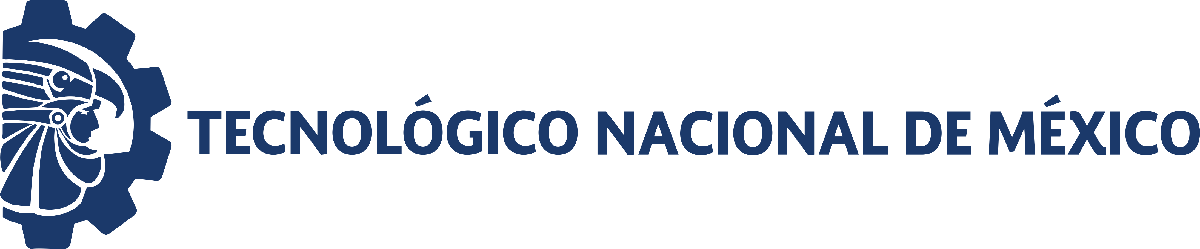                                 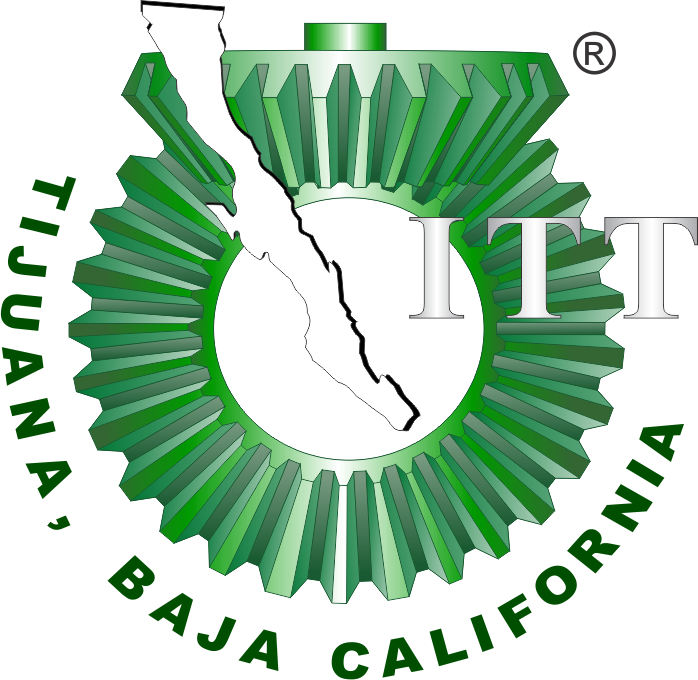

# Práctica uno: Diseño de controladores

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

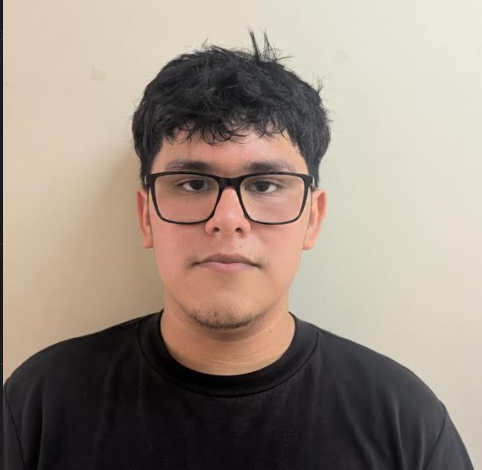

Nombre del alumno: Marco Antonio Garcia Montilla

Número de control: 22211756

Correo institucional: l22211756**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; format short; warning('off','all')
tend = 180; %tiempo de simulacion en dias 
dt = 1E-3; %intervalo de integracion para el metodo de soluciones por diferencias finitas
n = round(tend/dt); %cantidad de iteraciones para el metodo numerico 

%condiciones iniciales base para cada paciente
x1_0 = 59; x2_0 = 44; x3_0 = 885;
%parametros particulares para cada paciente 
gamma = [0.769; 0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.089; 0.243; 0.057];
beta = [1.650; 0.867; 1.617; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925; 0.879];

seed = 22211756; %semilla para asegurar reproducibilidad
rng(seed,'twister')
%intervalo de las condiciones iniciales
xmin = 0.99; xmax = 1.01;
interval = xmin + (xmax - xmin).*rand(numel(gamma),1);
%condiciones iniciales para cada paciente
x1_0 = x1_0*interval; disp('x1(0) = ');disp(x1_0');...
x2_0 = x2_0*interval; disp('x2(0) = ');disp(x2_0');...
x3_0 = x3_0*interval; disp('x3(0) = ');disp(x3_0');

x1(0) = 
   59.3204   58.5996   59.0489   58.4587   58.5613   58.4705   58.9690   58.7952   58.6129   58.5781



x2(0) = 
   44.2390   43.7014   44.0364   43.5963   43.6728   43.6051   43.9769   43.8473   43.7113   43.6853



x3(0) = 
  889.8063  878.9946  885.7328  876.8811  878.4191  877.0573  884.5357  881.9280  879.1937  878.6709



## Caso sin transfusion sanguinea [u(t) = 0]

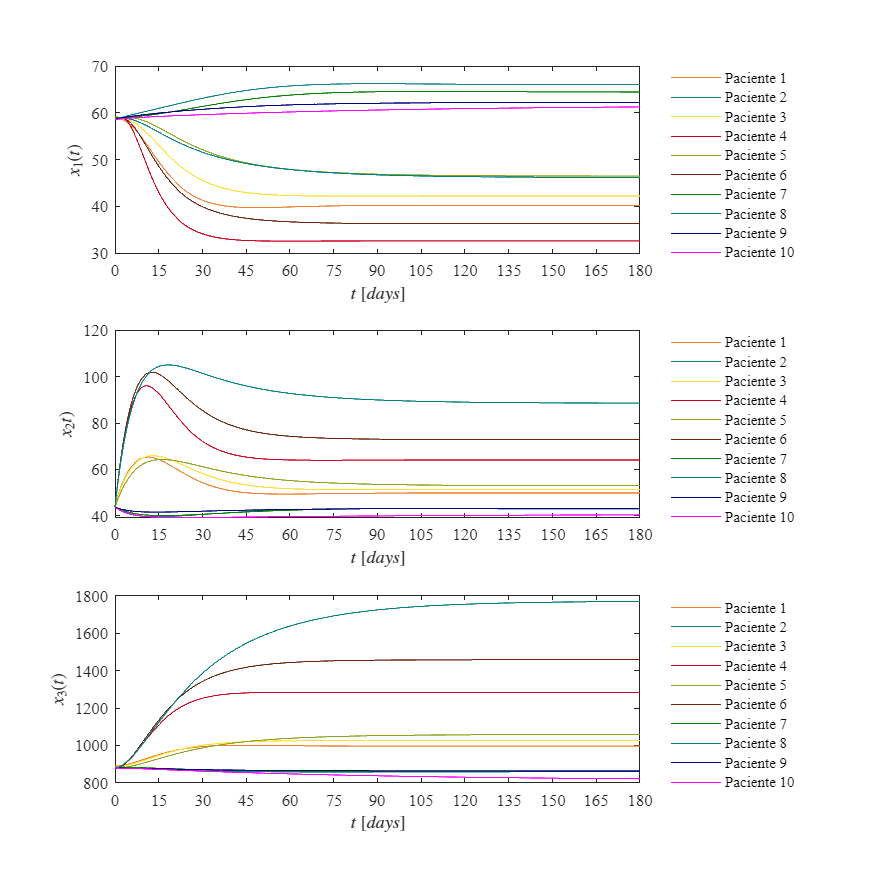

u = zeros(n+1,1); %no hay transfusion
fig = 1;
for i =1:10
[t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
plotdata(t,x1,x2,x3,fig)
end

## Caso con transfusion sanguinea 

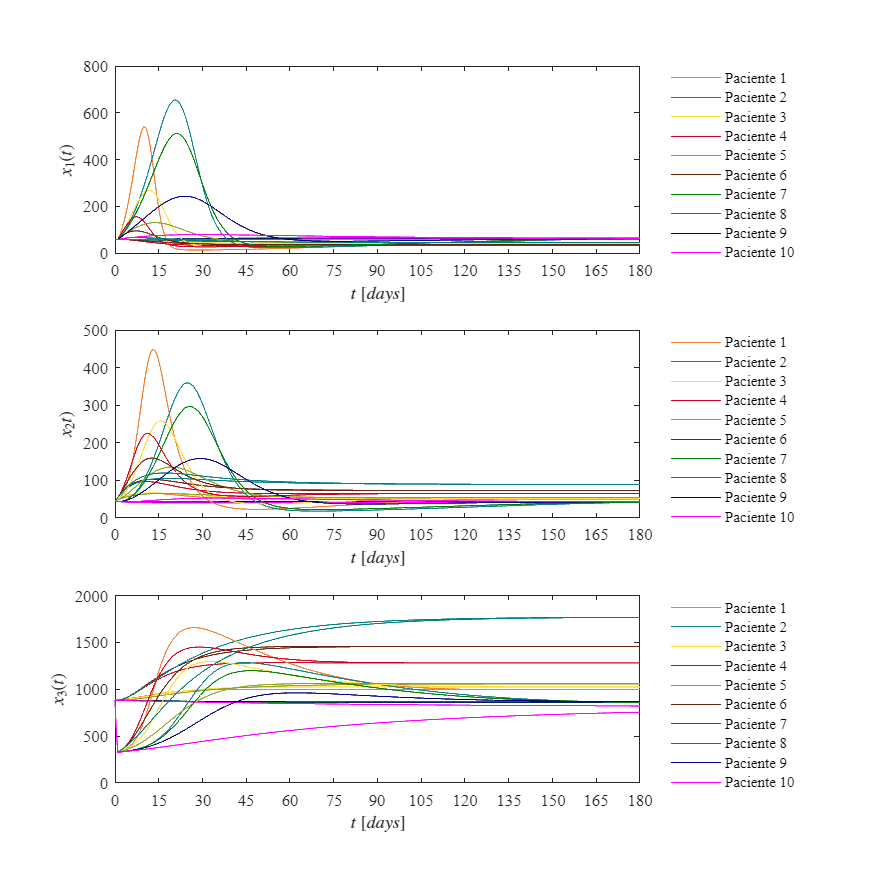

u(1:1/dt,1)=1;
fig = 2;
for i =1:10
[t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
plotdata(t,x1,x2,x3,fig)
end

## Función : Modelo matemático


$$\dot{{\dot{x} }_1 =\beta \left(X_0 -k_1 x_1 \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }}$$



$${\dot{x} }_2 =\beta \left(k_1 x_1 -k_2 x_2 \right)$$



$${\dot{x} }_3 =\beta \left(k_2 x_2 -\alpha x_3 \right)-u\left(t\right)x_3$$


function[t,x1,x2,x3] = system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
    Base = 885.42; X0 = 7.3785; k1 = 0.125; k2 = 0.1667; alpha = 0.00833;
    t = (0:dt:tend)';
    n = round (tend/dt);
    x1 = zeros(n+1,1);x1(1) = x1_0;
    x2 = zeros(n+1,1);x2(1) = x2_0;
    x3 = zeros(n+1,1);x3(1) = x3_0;
    for i = 1:n%metodo de euler(diferencias finitas)
        x1(i+1) = x1(i)+(beta*(X0 - k1*x1(i)) + gamma*(Base - x3(i))*(1 - u(i))*x1(i)/Base)*dt;
        x2(i+1) = x2(i) + (beta* k1*x1(i)- k2*x2(i))*dt;
        x3(i+1) = x3(i) + (beta*(k2*x2(i) - alpha*x3(i)) - u(i)*x3(i))*dt;

    end 
end

## Función:Respuesta a las señales

function plotdata(t,x1,x2,x3,fig)
    set(figure(fig),'Color','w')
    set(gcf,'Units','Centimeter','Position',[1,1,20,20])

    mycolors =[240,128,48;
                15,130,140;
                255,221,51;
                204,0,34;
                143,163,30;
                107,36,12;
                0, 128, 0;
                0, 128, 128;
                0, 0, 128;
                255, 0, 255]/255;
    colororder(mycolors)
    
    subplot(3,1,1)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x1)
    xlabel('$t$ $[days]$','Interpreter','Latex','FontSize',10)
    ylabel('$x_1(t)$','Interpreter','Latex','FontSize',10)
    xlim([0,180]); xticks(0:15:180)
    L = legend('Paciente 1','Paciente 2','Paciente 3','Paciente 4','Paciente 5','Paciente 6',...
        'Paciente 7','Paciente 8','Paciente 9','Paciente 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)
    
    subplot(3,1,2)
    hold on; grid off; box on;
    plot(t,x2)
    xlabel('$t$ $[days]$','Interpreter','Latex','FontSize',10)
    ylabel('$x_2t)$','Interpreter','Latex','FontSize',10)
    xlim([0,180]); xticks(0:15:180)
        L = legend('Paciente 1','Paciente 2','Paciente 3','Paciente 4','Paciente 5','Paciente 6',...
        'Paciente 7','Paciente 8','Paciente 9','Paciente 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)
    
    subplot(3,1,3)
    hold on; grid off; box on;
    plot(t,x3)
    xlabel('$t$ $[days]$','Interpreter','Latex','FontSize',10)
    ylabel('$x_3(t)$','Interpreter','Latex','FontSize',10)
    xlim([0,180]); xticks(0:15:180)
        L = legend('Paciente 1','Paciente 2','Paciente 3','Paciente 4','Paciente 5','Paciente 6',...
        'Paciente 7','Paciente 8','Paciente 9','Paciente 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)

    if fig == 1
        exportgraphics(gcf,['Caso sin transfusion','.pdf'],'ContentType','vector')
    elseif fig ==2
        exportgraphics(gcf,['Caso con transfusion','.pdf'],'ContentType','vector')
    end
end
